%Clear workspace
clear
%Clear command window
clc

%%User input to open text file
%Make sure the file is in your MATLAB Current Folder' window
filename = uigetfile('*.txt');
fileID = fopen(filename,'r');

%%Import every nth line of data

%Initialize index
m = 1;

% Skip 13 headerlines
for n=1:13
  tline = fgetl(fileID);
end

%Add every nth line 
while ischar(tline)
    tline = fgetl(fileID);
    A{m} = tline;
    m = m+1;
    tline = fgetl(fileID);
  %Skip next n lines
  %Change the upper limit of n to change how often code reads a line
  for n=1:9999
    tline = fgetl(fileID);
  end
end

fclose(fileID);

%Initialize column header names
%Used in table below
columnNames = {'DateTime','EB','C001','C002','C003','C004','C005','C006','C007','C008','C009','C010','C011','C012','C013','C014','C015','C016','C017','C018','C019','C020','C021','C022','C023','C024','C025','C026','C027','C028','C029','C030','C031','C032','C033','C034','C035','C036','C037','C038','C039','C040','C041','C042','C043','C044','C045','C046','C047','C048','C049','C050','C051','C052','C053','C054','C055','C056','C057','C058','C059','C060','C061','C062','C063','C064','C065','C066','C067','C068','C069','C070','C071','C072','C073','C074','C075','C076','C077','C078','C079','C080','C081','C082','C083','C084','C085','C086','C087','C088','C089','C090','C091','C092','C093','C094','C095','C096','C097','C098','C099','C100','C101','C102','C103','C104','C105','C106','C107','C108','C109','C110','C111','C112','C113','C114','C115','C116','C117','C118','C119','C120','C121','C122','C123','C124','C125','C126','C127','C128','C129'};

%%Convert all rows of data into table D

%Create Table D
%Convert A(2) into a cell array of split strings B2
B2 = strsplit(char(A(2)),'\t');
%Format columns 4:end to numbers (leave columns 1:3 as strings)
C2 = [datestr(B2(1));cellfun(@str2num,B2(2:end),'un',0).'].';
%Convert first row of data C(2) into table D
D = cell2table(C2);
%Set table variable names
D.Properties.VariableNames = columnNames;

%Add rows to existing table D
for p = 2:m-1
    B3 = strsplit(char(A(p)),'\t');
    C3 = [datestr(B3(1));cellfun(@str2num,B3(2:end),'un',0).'].';
    Dnew = cell2table(C3);
    Dnew.Properties.VariableNames = columnNames;
    %Add new row to existing table D
    D = [D;Dnew];
end

%Convert first column from string to Date and Time
D.DateTime = datetime(D.DateTime);
%%Name the contents of the 

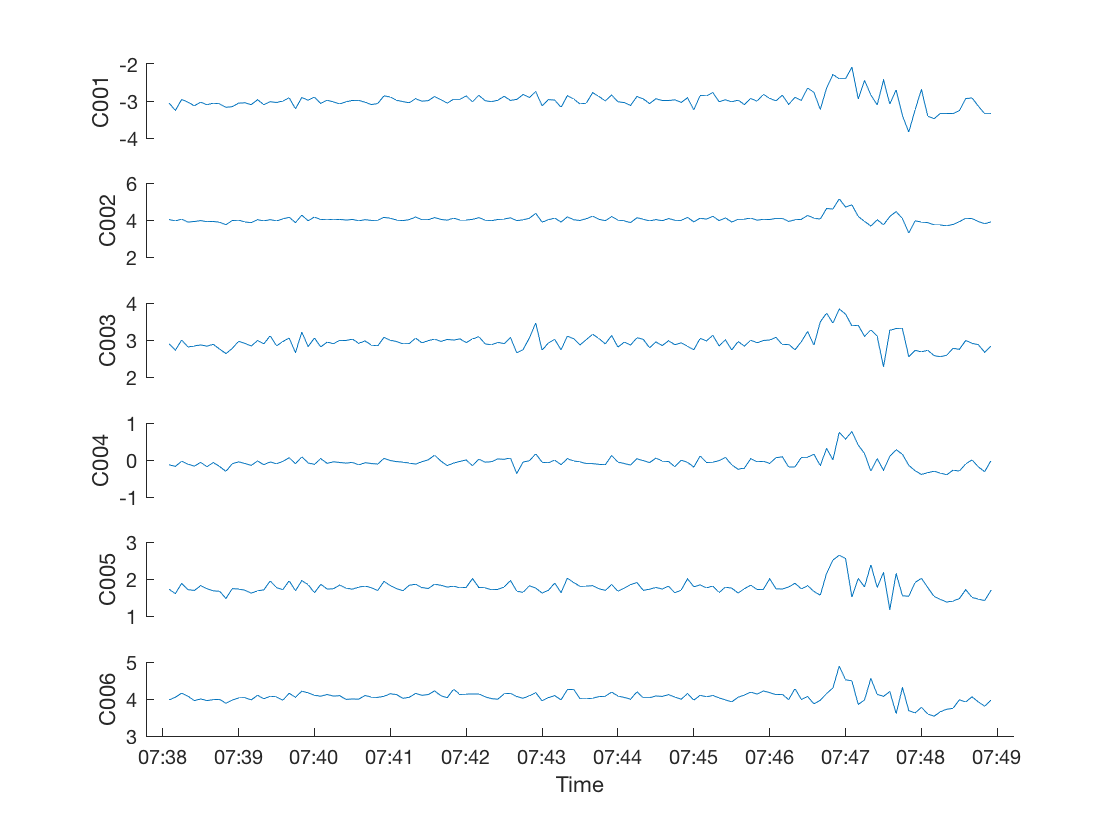

%%Plot Data Columns in Table

%Set number of columns to plot starting at column D.C001 = D{:,3}
%Trying to plot all of them, but they get hella cramped
z = 6;

%Initialize x axis = time
xx = D.DateTime;

%Plot each column (C001-Cz) as a subplot with common x axis = time
figure('color', 'w');
for i=1:z
   h(i) = subplot(z,1,i);
   plot(xx,D{:,i+2})
   ylabel(D.Properties.VariableNames{i+2})
end
set(h, 'box', 'off');
set(h(1:i-1),'xcolor','w');
xlabel ('Time')

%Export table D to csv file
filename = 'DataTable.csv';
writetable(D,filename,'Delimiter',',')